# Test out PID gain interpolation

% Saved gains after tuning
PIDDz_save = [400 2000 3200 3200 0.002; 
              310  350 5500 4000 0.005]

PIDDz_save = 1.0e+03 *

    0.4000    2.0000    3.2000    3.2000    0.0000
    0.3100    0.3500    5.5000    4.0000    0.0000



% Current situation (inputs)
Zd = 0.0030;
dz = 0.000240;
P_override = nan;
I_override = nan;
D_override = nan;


% Read recorded PID gains
Zq = Zd;

Ps = PIDDz_save(:,1);
Is = PIDDz_save(:,2);
Douts = PIDDz_save(:,3);
Dins = PIDDz_save(:,4);
Zs = PIDDz_save(:,5);
[~,lowest_index] = min(Zs);
[~,highest_index] = max(Zs);


% Interpolate if necessary!
if Zd <= Zs(lowest_index)
    disp("Below 2mm!")
    P_final = Ps(lowest_index);
    I_final = Is(lowest_index);
    Dout_final = Douts(lowest_index);
    Din_final  = Dins(lowest_index);
elseif Zd >= Zs(highest_index)
    disp("Above 5mm!")
    P_final = Ps(highest_index);
    I_final = Is(highest_index);
    Dout_final = Douts(highest_index);
    Din_final  = Dins(highest_index);
else
    disp("Interpolate!")
    P_final     = interp1(Zs,Ps,Zq,'spline');
    I_final     = interp1(Zs,Is,Zq,'spline');
    Dout_final  = interp1(Zs,Douts,Zq,'spline');
    Din_final   = interp1(Zs,Dins,Zq,'spline');
end

Interpolate!





% Choose between "inner" and "outer" D gains
z = Zd - dz;
dz_inner_threshold = 0.1;  % Within this, "inner" D will be applied
dz_outer_threshold = 0.25;   % Beyond this, "outer" D will be applied
dz_mm = dz * 1000;

if abs(dz_mm) <= dz_inner_threshold
    disp("Within inner threshold")
    D_final = Din_final;
elseif abs(dz_mm) >= dz_outer_threshold
    disp("Beyond outer threshold")
    D_final = Dout_final;
else
    disp("In between; interpolate!")
    D_final = ( Dout_final- Din_final)*(abs(dz_mm) - dz_inner_threshold)/(dz_outer_threshold - dz_inner_threshold) +  Din_final;
end

In between; interpolate!




% Apply overrides (if any)
if ~isnan(P_override)
    P_final = P_override;
end
if ~isnan(I_override)
    I_final = I_override;
end
if ~isnan(D_override)
    D_final = D_override;
end
PID_out = [P_final, I_final, D_final]

PID_out = 1.0e+03 *

    0.3700    1.4500    3.9333





% figure
% P_outies2 = interp1(Zs,Ps,Zq,'spline');
% plot(Zs,Ps,'o',Zq,P_outies2,':.');
% title('Spline Interpolation for P');
% xlabel('z (mm)')
% ylabel('P gain')

## test

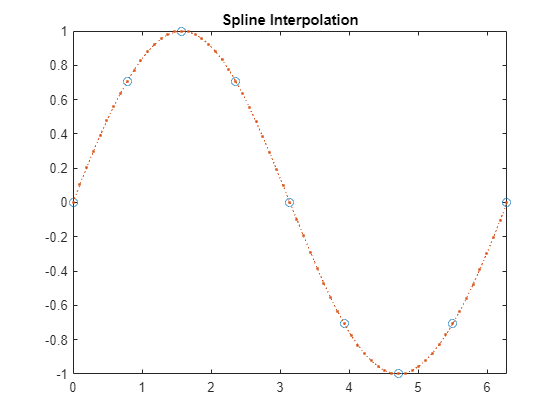

x = 0:pi/4:2*pi; 

v = sin(x);
xq = 0:pi/32:2*pi;


figure
vq2 = interp1(x,v,xq,'spline');
plot(x,v,'o',xq,vq2,':.');
xlim([0 2*pi]);
title('Spline Interpolation');
